# Trabajo 2 --Teoría de las telecomunicaciones 1

Universidad del Cauca - 2021-1

Grupo A12 - Nicolás Chicaiza y Nicolás Zambrano

### 1. GRAFICA DE SEÑAL ASIGNADA

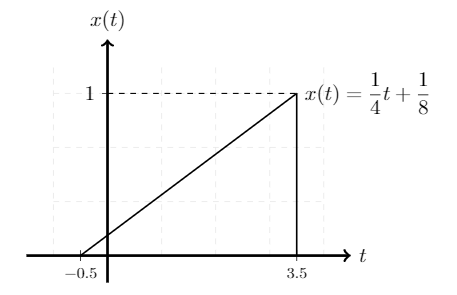

### 2. MODIFICACION DE PARAMETROS 

clear; %Limpio Espacio de trabajo
clc;

A=1; %Amplitud rampa (Multiplicacion por un escalar)
sh=0.5; %Desplazamiento en el tiempo (Normalizado solo para valores positivos)
T=4; %Periodo rampa (Igual al taller 1)
esc=1; %Cambio de Escala
shf=0; %Desplazamiento en frecuencia
np=0.001; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
fs=1/(T*np); %Frecuencia de muestreo
t=-(T+sh):np*T:(T+sh); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)


ramp=(A/T)*((t*esc)+sh); %Defino la pendiente de las rampas y creo el vector rampa con respecto al tiempo
ps=ramp.*rectpuls(((t*esc)+sh)-(T/2),(T)); %Acoto el vector rampa con un pulso rectangular de origen en 0 y ancho Tr
ps=ps.*exp(i*2*pi*shf*t);

### 3. CALCULO DE TRANSFORMADA DE FOURIER (SIMBOLICA)

Verificación de cálculos

%---------------------------Transformada pulso rampa--------------------------
syms x f;
dif=((A/T)*(((x*esc)+sh))*exp(i*2*pi*shf*x)*exp(-i*2*pi*f*x)); %Expresion dentro de la integral de la transformada de Fourier
trfu=int(dif,[(0-sh)/esc (T-sh)/esc]) %Integral definida en el periodo de la rampa

$$trfu = \frac{{\mathrm{e}}^{-3\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right)}{16\,f^{2}\,\pi^{2}}$$

trfum=simplify(abs(trfu))

$$trfum = \frac{{\mathrm{e}}^{3\,\pi \,\mathrm{imag}\left(f\right)}\,\left|1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right|}{16\,\pi^{2}\,{\left|f\right|}^{2}}$$

%trfua=simplify(angle(trfu))
double(limit(trfum))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud del nivel DC

ans = 2

double(simplify(abs(limit(trfum,f,1))))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud en f=1

ans = 0.1592

%-----------------------------------------------------------------------------

### 4. CALCULO DE TRANSFORMADA DE FOURIER INVERSA (SIMBOLICA)

Comprobación de Dualidad

%---------------------------TF Inversa para demostracion de dualidad--------------------------
%syms x f;
%difi=(trfu*exp(i*2*pi*f*(x))) %Expresion dentro de la integral de la transformada de Fourier
%trfi=int(difi,'f',[-inf inf]) %Integral definida en el periodo de la rampa
%trfi=simplify(abs(trfi))
%double(limit(trfi))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud del nivel DC
%double(simplify(abs(subs(trfi,f,1))))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud en f=1
%-----------------------------------------------------------------------------

### 5. TRANSFORMADA DE FOURIER DESDE LA EXPRESION (SIMBOLICA)

Gráficas de cálculos

%---------------------------TF Simbolica--------------------------
tic
Pts=1000;%Numero de muestras a evaluar en la ecuacion simbolica
fsimb=linspace(-3,3,Pts);
Xfsimb=linspace(0,0,Pts);
Afsimb=linspace(0,0,Pts);
for(n=1:length(fsimb))
    if(fsimb(n)==shf) %Condicional para evitar la indeterminacion de la expresion simbolica en f=shf
        Xfsimb(n)=limit(trfum,f,fsimb(n))
    else
        Xfsimb(n)=subs(trfum,f,fsimb(n));
    end
    %Afsimb(n)=subs(trfua,f,fsimb(n));
end
tiesimbolica=toc

tiesimbolica = 23.3167

%-----------------------------------------------------------------------------

### 6. CALCULO DE TRANSFORMADA RAPIDA DE FOURIER (FFT)

Gráficas de FFT

%--------------------CALCULO FFT---------------------------
tic
Pt=10;%Coeficiente multiplicador de cantidad de puntos en la transformada rapida de Fourier
N=Pt*(2^(nextpow2(length(ps))));%Calculo de la potencia de 2 mas cercana a la longitud de la señal de entrada (Para eficiencia computacional)
Tf=fft(ps,N);
Xf=abs(fftshift(Tf))/fs; % Transformada FFT Normalizada
Af=angle(fftshift(Tf))/fs;
f=linspace(-fs/2,fs/2,length(Xf));
%f=f./T;%Normalizacion en frecuencia
tierapida=toc

tierapida = 0.0397

%-----------------------------------------------------------------------------
ratioabs=N/length(t); %razon entre el tamaño del vector tiempo y el tamaño del vector de la transformada de Fourier
ratiotf=tiesimbolica/tierapida;

### 7. CALCULO DE TRANSFORMADA DE FOURIER INVERSA (IFFT)

Gráfica de IFFT

%--------------------CALCULO FFT Inversa---------------------------
tic
Xt=abs(fftshift(fft(Tf))/N); % Transformada FFT Normalizada
ti=linspace(-ratioabs*(T+sh),ratioabs*(T+sh),length(Xt)); %Espacio vectorial del tiempo normalizado
ti=ti+(T+sh); %corrimiento del vector tiempo para ajuste de desfase
tieinversa=toc

tieinversa = 0.0505

%-----------------------------------------------------------------------------

### 8. GRAFICAS DE RESULTADOS

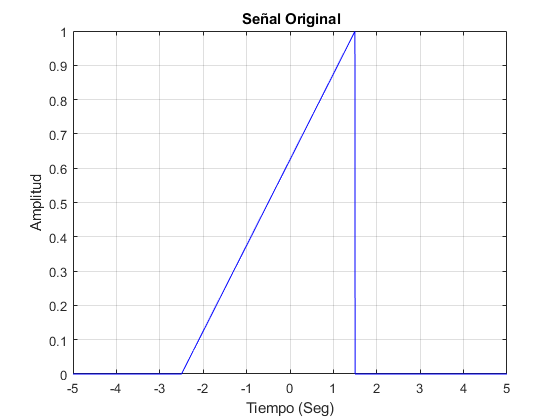

%--------------------Graficacion de Resultados---------------------------
plot(t,abs(ps),'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf Señal Original');

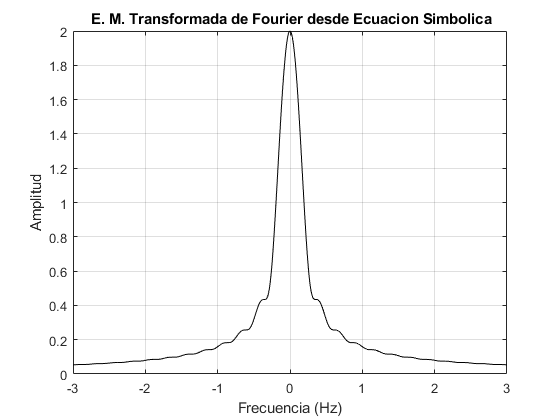

plot(fsimb,Xfsimb,'black'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. M. Transformada de Fourier desde Ecuacion Simbolica');

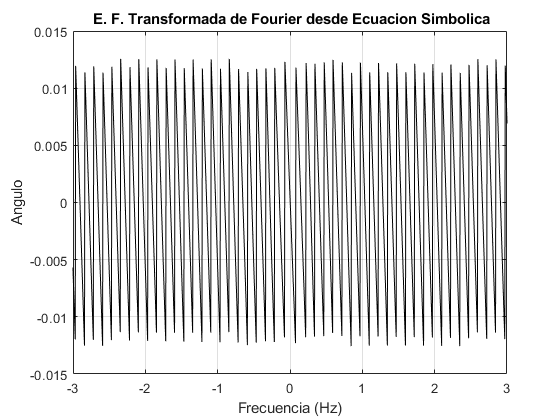

plot(f,Af,'black'),grid on,xlabel 'Frecuencia (Hz)', ylabel Angulo;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. F. Transformada de Fourier desde Ecuacion Simbolica');

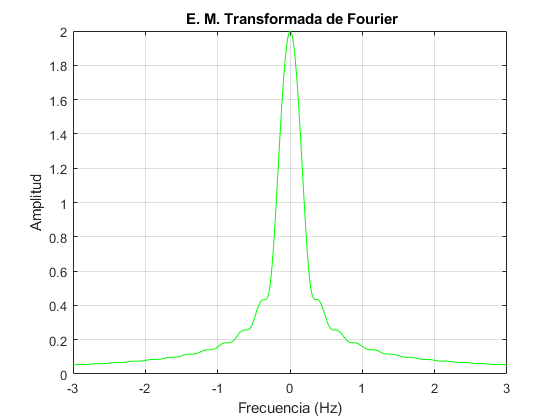


plot(f,Xf,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. M. Transformada de Fourier');

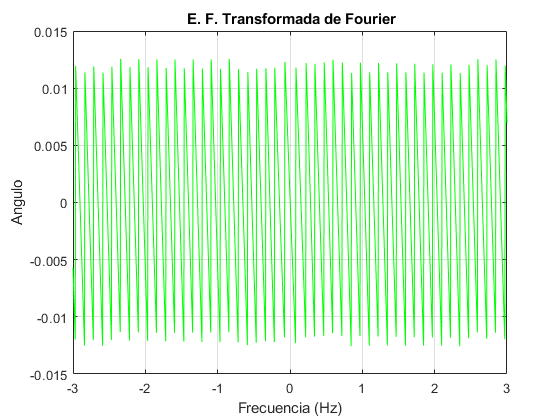

plot(f,Af,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Angulo;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. F. Transformada de Fourier');

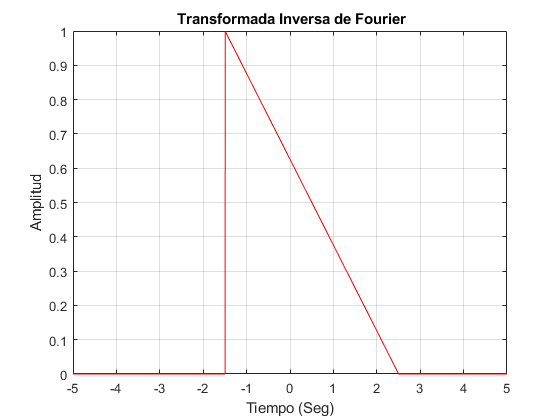



plot(ti,Xt,'r'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf Transformada Inversa de Fourier');

%-----------------------------------------------------------------------------